Model for the control of Rotation Plane

clc
close all
clearvars
addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data'))
%Define important points for plot

cg   = [0,0,0];
s    = [-3.5, 0,0]/100;
rp   = cg + s;
beta = deg2rad(45);%pi/2;
g =9.81;
mass = 2.339132*1; %kg
% Motor position definition

m1_arm = [34.5, 0, 0]/100;
m1     = m1_arm+rp;
m2_arm = -m1_arm;
m2     = m2_arm + rp;

m3_arm = [cos(beta), sin(beta), 0]*31/100;
m3     = m3_arm + rp;
m4_arm = [cos(beta+pi), sin(beta+pi), 0]*31/100;
m4     = m4_arm + rp;

m5 = [-50,0,0]/100;

Symbolic equations

syms beta_s rp_s
eff_mat = [0, -12.8, 0, 12.8; 2.7, 0, -2.7, 0; -0.115, 0.115, -0.115, 0.115; -0.3, -0.3, -0.3, -0.3]

eff_mat =          0  -12.8000         0   12.8000
    2.7000         0   -2.7000         0
   -0.1150    0.1150   -0.1150    0.1150
   -0.3000   -0.3000   -0.3000   -0.3000



m1_arm_s = [34.5, 0, 0]/100;
m1_s     = m1_arm_s+rp_s;
m2_arm_s = -m1_arm_s;
m2_s     = m2_arm_s + rp_s;

m3_arm_s = [cos(beta_s), sin(beta_s), 0]*31/100;
m3_s     = m3_arm_s + rp_s;
m4_arm_s = [cos(beta_s+pi), sin(beta_s+pi), 0]*31/100;
m4_s    = m4_arm_s + rp_s;

arm_tot(beta_s,rp_s) = [m1_s.',m4_s.',m2_s.',m3_s.']

$$arm\_tot(beta\_s, rp\_s) = \left(\begin{array}{cccc} {\mathrm{rp}}_{s}+\frac{69}{200} & {\mathrm{rp}}_{s}-\frac{31\,\cos\left(\beta_{s}\right)}{100} & {\mathrm{rp}}_{s}-\frac{69}{200} & {\mathrm{rp}}_{s}+\frac{31\,\cos\left(\beta_{s}\right)}{100}\\ {\mathrm{rp}}_{s} & {\mathrm{rp}}_{s}-\frac{31\,\sin\left(\beta_{s}\right)}{100} & {\mathrm{rp}}_{s} & {\mathrm{rp}}_{s}+\frac{31\,\sin\left(\beta_{s}\right)}{100}\\ {\mathrm{rp}}_{s} & {\mathrm{rp}}_{s} & {\mathrm{rp}}_{s} & {\mathrm{rp}}_{s} \end{array}\right)$$

mom_tot(beta_s, rp_s) = cross(arm_tot(beta_s,rp_s),[0,0,0,0;0,0,0,0;-1,-1,-1,-1])

$$mom\_tot(beta\_s, rp\_s) = \left(\begin{array}{cccc} -{\mathrm{rp}}_{s} & \frac{31\,\sin\left(\beta_{s}\right)}{100}-{\mathrm{rp}}_{s} & -{\mathrm{rp}}_{s} & -{\mathrm{rp}}_{s}-\frac{31\,\sin\left(\beta_{s}\right)}{100}\\ {\mathrm{rp}}_{s}+\frac{69}{200} & {\mathrm{rp}}_{s}-\frac{31\,\cos\left(\beta_{s}\right)}{100} & {\mathrm{rp}}_{s}-\frac{69}{200} & {\mathrm{rp}}_{s}+\frac{31\,\cos\left(\beta_{s}\right)}{100}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

res = mom_tot(beta_s, 0)

$$res = \left(\begin{array}{cccc} 0 & \frac{31\,\sin\left(\beta_{s}\right)}{100} & 0 & -\frac{31\,\sin\left(\beta_{s}\right)}{100}\\ \frac{69}{200} & -\frac{31\,\cos\left(\beta_{s}\right)}{100} & -\frac{69}{200} & \frac{31\,\cos\left(\beta_{s}\right)}{100}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Import motor models

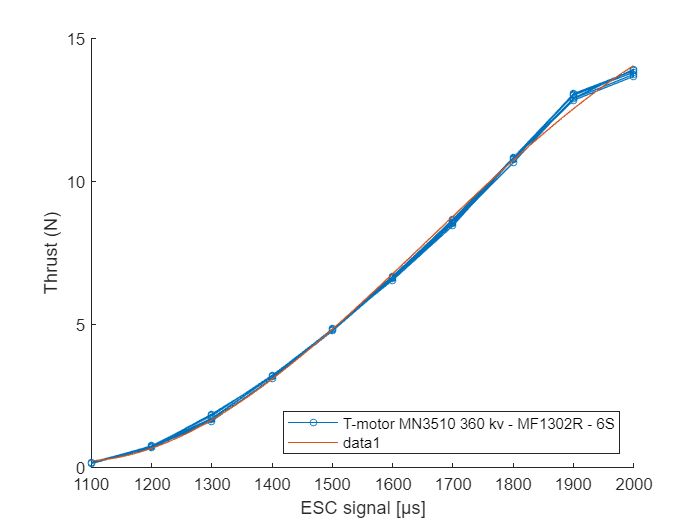

% Folder in which all test data folders are located
rcbench_folder = 'RC Testbench Data/RC Testbench Data';
%'C:\Users\Tomaso\Desktop\Thesis\main\RC Testbench Data\RC Testbench Data';

% List of folders of the specific tests
test_folder = {...'T-motor F80 Pro 1900 kv - GemFan 6030 4R(green) - 4S'
              ...'T-motor F80 Pro 1900 kv - Qprop 5x4x3 (pink) - 4S'
              ...'T-motor F80 Pro 1900 kv 7x4R (orange) - 4S'
              ...'T-motor MN3515 400 kv - APC 13x10EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 14x8.5EP - 6S - Pusher'
              ...'T-motor MN3515 400 kv - APC 16x10EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 4S'
              ...'T-motor MN3510 360 kv - APC 11x5.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x6 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 12x12 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 13x10 EP - 6S - Pusher'
              ...'T-motor MN3510 360 kv - APC 14x8.5 EP - 6S'
              ...'T-motor MN3510 360 kv - APC 16x10 EP - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S'
              ...'T-motor MN3510 360 kv - MF1302R - 4S - Pusher'
              'T-motor MN3510 360 kv - MF1302R - 6S'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - pusher - esc settings'
              ...'T-motor MN3510 360 kv - MF1302R - 6S - Pusher - ESC 48 khz'
              ...'T-motor MN3510 360 kv - MF1302R FW folding hub - 6S - Pusher'
              };

%% Get the data
for n = 1:length(test_folder)
    folder = fullfile(rcbench_folder, test_folder{n});
    data{n} = RCTestbench.getData(folder);
%     data{n} = data{n}.getFOM;
end

pwm = [data{1,1}.perf.test1.pwm;data{1,1}.perf.test2.pwm;data{1,1}.perf.test3.pwm];
T =  [data{1,1}.perf.test1.T;data{1,1}.perf.test2.T;data{1,1}.perf.test3.T];
Qm =  [data{1,1}.perf.test1.Qm;data{1,1}.perf.test2.Qm;data{1,1}.perf.test3.Qm];
deg=3;
p_T = polyfit(pwm,T,deg);
p_Qm = polyfit(pwm,Qm,deg);
pwm1= linspace(min(pwm),max(pwm));
T_f = polyval(p_T,pwm1);
Qm_f = polyval(p_Qm,pwm1);

figure(1)
clf
%plot(pwm,T)
hold on
for n = 1:length(data)
    data{n}.perfplt('pwm', 'T')
end
plot(pwm1,T_f)

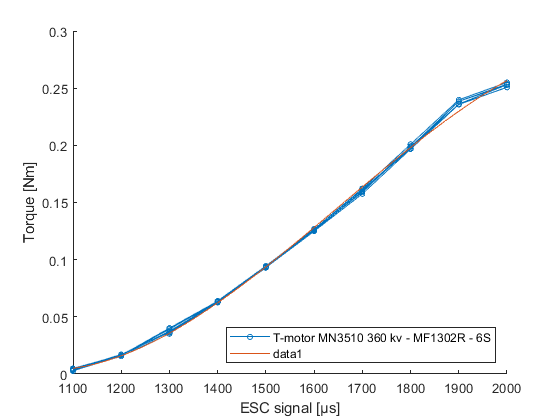


figure(2)
clf
%plot(pwm,Qm)
hold on
for n = 1:length(data)
    data{n}.perfplt('pwm', 'Qm') 
end
plot(pwm1,Qm_f)

Force vectors calculations

m1_t = force(unitvect(cg,m1),[0,0,1],deg2rad(0));
m2_t = force(unitvect(cg,m2),[0,0,1],deg2rad(0));
m3_t = force(unitvect(rp,m3),[0,0,1],deg2rad(0));
m4_t = force(unitvect(rp,m4),[0,0,1],deg2rad(0));
m5_t = force(unitvect(cg,m5),[1,0,0],deg2rad(0));
cg_w = [0,0,-1]*mass*g;

Force and Moment static balances

EF = m1_t+m2_t+m3_t+m4_t+m5_t+cg_w ;

Unrecognized function or variable 'm1_t'.

EM = cross(m1,m1_t)+cross(m2,m2_t)+cross(m3,m3_t)+cross(m4,m4_t)+cross(m5,m5_t);
%conversion from gmm^2 to kgm^2 is 10^-9
angles = [pi/2,pi/4,0];
Ixx = [2.049e-2,2.394e-2, 2.862e-2];
Ixy = [2.593e-4,4.258e-3,1.113e-4];
Iyx = [2.593e-4,4.258e-3,1.113e-4];
Iyy = [2.065e-1,2.028e-1, 1.979e-1];
Ixz = [8.238e-3,8.079e-3,7.977e-3];%*10^-1;%e-3
Iyz = [-2.422e-4,-2.005e-4,-2.7692e-5];
Izx = [8.238e-3,8.079e-3,7.977e-3];%*10^-1;%e-3
Izy = [-2.422e-4,-2.005e-4,-2.7692e-5];
Izz = [2.164e-1,2.161e-1,2.158e-1];
tensor = [ interp1(angles,Ixx,beta) interp1(angles,Ixy,beta) interp1(angles,Ixz,beta); 
           interp1(angles,Iyx,beta) interp1(angles,Iyy,beta) interp1(angles,Iyz,beta); 
           interp1(angles,Izx,beta) interp1(angles,Izy,beta) interp1(angles,Izz,beta)];%.*10000/100;    %10000 from kg m^2 to kg cm^2, 1000 for conversion of N



Optimizer: new

bypass = 0;
if bypass
    wanted_acc = [50 20 0 ].';
    tn = tensor * wanted_acc;
    prob = optimproblem;
    x = optimvar('x',5,1,'LowerBound',min(pwm)*[1 1 1 1 0],'UpperBound',max(pwm));
    f = [1 1 1 1 5];
    prob.Constraints.cons1= [m1_t.',m2_t.',m3_t.',m4_t.',m5_t.']*(p_T(1)*x.^3+p_T(2)*x.^2+p_T(3)*x+p_T(4))>=[1 0 -cg_w(3)].'; %(polyval(p_T,x) 
    prob.Constraints.cons2= [cross(m1,m1_t).',cross(m2,m2_t).',cross(m3,m3_t).',cross(m4,m4_t).',cross(m5,m5_t).']*(p_T(1)*x.^3+p_T(2)*x.^2+p_T(3)*x+p_T(4))+[-m1_t.',-m2_t.',m3_t.',m4_t.',m5_t.']*(p_Qm(1)*x.^3+p_Qm(2)*x.^2+p_Qm(3)*x+p_Qm(4))==[tn(1) tn(2) tn(3)].';
    
    prob.Objective = f*x;
    x0.x= ones(5,1)*0.9*max(pwm);
    [sol,fval1,exitflag,output1] = solve(prob,x0);
    result = sol.x/max(pwm)*100;
    disp(result)
end

Plots to visualise the model

%check
if bypass 
    res1=[m1_t.',m2_t.',m3_t.',m4_t.',m5_t.']*(p_T(1)*sol.x.^3+p_T(2)*sol.x.^2+p_T(3)*sol.x+p_T(4))
    res2=[cross(m1,m1_t).',cross(m2,m2_t).',cross(m3,m3_t).',cross(m4,m4_t).',cross(m5,m5_t).']*(p_T(1)*sol.x.^3+p_T(2)*sol.x.^2+p_T(3)*sol.x+p_T(4))+[-m1_t.',-m2_t.',m3_t.',m4_t.',m5_t.']*(p_Qm(1)*sol.x.^3+p_Qm(2)*sol.x.^2+p_Qm(3)*sol.x+p_Qm(4))
    line_size=1.5;
    figure(22)
    clf
    h1=plot3(cg(1),cg(2),cg(3),'.b','MarkerSize',20);
    hold on
    h2=plot3(rp(1),rp(2),rp(3),'.r','MarkerSize',20);
    h3=plot3(m1(1),m1(2),m1(3),'.g','MarkerSize',20);
    h4=plot3(m2(1),m2(2),m2(3),'.g','MarkerSize',20);
    h5=plot3(m3(1),m3(2),m3(3),'.g','MarkerSize',20);
    h6=plot3(m4(1),m4(2),m4(3),'.g','MarkerSize',20);
    h9=plot3(m5(1),m5(2),m5(3),'.c','MarkerSize',20);
    h7=plot3([m1(1) m5(1)],[m1(2) m5(2)],[m1(3) m5(3)],'-k','MarkerSize',20);
    h8=plot3([m3(1) m4(1)],[m3(2) m4(2)],[m3(3) m4(3)],'-k','MarkerSize',20);
    factor = 0.02;
    h10=quiver3(m1(1),m1(2),m1(3),m1_t(1)*polyval(p_T,sol.x(1)),m1_t(2)*polyval(p_T,sol.x(1)),m1_t(3)*polyval(p_T,sol.x(1)),'-r','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    h11=quiver3(m2(1),m2(2),m2(3),m2_t(1)*polyval(p_T,sol.x(2)),m2_t(2)*polyval(p_T,sol.x(2)),m2_t(3)*polyval(p_T,sol.x(2)),'-r','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    h12=quiver3(m3(1),m3(2),m3(3),m3_t(1)*polyval(p_T,sol.x(3)),m3_t(2)*polyval(p_T,sol.x(3)),m3_t(3)*polyval(p_T,sol.x(3)),'-r','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    h13=quiver3(m4(1),m4(2),m4(3),m4_t(1)*polyval(p_T,sol.x(4)),m4_t(2)*polyval(p_T,sol.x(4)),m4_t(3)*polyval(p_T,sol.x(4)),'-r','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    h14=quiver3(m5(1),m5(2),m5(3),-m5_t(1)*polyval(p_T,sol.x(5)),-m5_t(2)*polyval(p_T,sol.x(5)),-m5_t(3)*polyval(p_T,sol.x(5)),'-r','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    h15=quiver3(cg(1),cg(2),cg(3),cg_w(1),cg_w(2),cg_w(3),'-b','LineWidth',line_size,'AutoScale',1,'AutoScaleFactor',factor);
    % h8=quiver3(m3(1),m3(2),m3(3),m4(1),m4(2),m4(3),'AutoScale','off','LineWidth',line_size,"ShowArrowHead","off");
    
    % xlim([-25,25])
    % ylim([-25,25])
    
    axis equal
    zlim([-0.2,0.2])
    set(gca,'fontsize',10)
    grid minor
    grid on
    ylabel('North')
    xlabel('East')
    zlabel('Up')
    legend('CG','Rotation point')
end



Develop standardised test (new)

lim1=210;%200 170
lim2=30;
lim3=3;

alpha_x = linspace(-lim1,lim1,23);%51
[~,idx1]=sort(abs(alpha_x),'descend');
alpha_x_s = [alpha_x(idx1)];
alpha_y = linspace(-lim2,lim2,23);
[~,idx2]=sort(abs(alpha_y),'ascend');
alpha_y_s = [alpha_y(idx2)];
%alpha_y_s = [0,alpha_y_s(2:end)]
alpha_z = linspace(-lim3,lim3,23);
[~,idx3]=sort(abs(alpha_z),'ascend');
alpha_z_s = [alpha_z(idx3)];

[AX,AY,AZ] = meshgrid(alpha_x_s,alpha_y_s,alpha_z_s);
tester = zeros(size(alpha_x_s,2),size(alpha_y_s,2),size(alpha_z_s,2));
fi = waitbar(0, 'Starting');

Error using waitbar (line 120)
Improper arguments for waitbar.

Caused by:
    Error using appdesservices.internal.interfaces.model.AbstractModel/parsePVPairs (line 198)
    Functionality not supported with figures created with the figure f

for i =1:size(alpha_x_s,2)
    if i>1 && sum(sum(tester(i-1,end-1:end,end-1:end)))==4
        break
    end
    check_j=0;
    for j =1:size(alpha_y_s,2)
        if check_j ==1
            break
        end
%         check_k=find(tester(i,j-1,:),1,'last');
           
        for k =1:size(alpha_z_s,2)
            wanted_acc = [alpha_x_s(i) alpha_y_s(j) alpha_z_s(k)].';
            tn = tensor * wanted_acc;
            prob = optimproblem;
            x = optimvar('x',5,1,'LowerBound',min(pwm)*[1 1 1 1 0],'UpperBound',max(pwm));
            f = [1 1 1 1 5];
            prob.Constraints.cons1= [m1_t.',m2_t.',m3_t.',m4_t.',m5_t.']*(p_T(1)*x.^3+p_T(2)*x.^2+p_T(3)*x+p_T(4))>=[0 0 -cg_w(3)].'; %(polyval(p_T,x) 
            prob.Constraints.cons2= [cross(m1,m1_t).',cross(m2,m2_t).',cross(m3,m3_t).',cross(m4,m4_t).',cross(m5,m5_t).']*(p_T(1)*x.^3+p_T(2)*x.^2+p_T(3)*x+p_T(4))+[-m1_t.',-m2_t.',m3_t.',m4_t.',m5_t.']*(p_Qm(1)*x.^3+p_Qm(2)*x.^2+p_Qm(3)*x+p_Qm(4))==[tn(1) tn(2) tn(3)].';
            prob.Objective = f*x;
            x0.x= ones(5,1)*0.8*max(pwm); 
            [sol,fval1,exitflag,output1] = solve(prob,x0,"Options",optimoptions('fmincon','Display','none'));
            %iter=[i,j,k]
            %val =[alpha_x_s(i),alpha_y_s(j),alpha_z_s(k)]
        
            if exitflag == 1
                %disp('solution')
                tester(i,j,k)=1;
            elseif k>1 && exitflag ~= 1 && tester(i,j,k-1)==0
                break
                %disp('NOT')
            elseif k==1 && exitflag ~= 1
                check_j =1;
                break
            end             
        end    
    end
    waitbar(i/size(alpha_x_s,2), fi, sprintf('Progress: %d %%', floor(i/size(alpha_x_s,2)*100)));
    pause(0.1);
end
close(fi)

indici = find(tester);
[row, col, page] = ind2sub(size(tester), indici);

figure(4)
clf
plot3(0,0,0)
%scatter3(alpha_x_s(row),alpha_y_s(col),alpha_z_s(page),'.r')
hold on 
bnd = boundary([alpha_x_s(row).',alpha_y_s(col).',alpha_z_s(page).'],0)
trisurf(bnd,alpha_x_s(row),alpha_y_s(col),alpha_z_s(page),'Facecolor','blue','FaceAlpha',0.1)

%scatter3(AX(motor6s_90==1),AY(motor6s_90==1),AZ(motor6s_90==1),'.b') 
% bnd = boundary([AX(motor6s_90==1),AY(motor6s_90==1),AZ(motor6s_90==1)],0)
% trisurf(bnd,AX(motor6s_90==1),AY(motor6s_90==1),AZ(motor6s_90==1),'Facecolor','red','FaceAlpha',0.1)
xlim([-lim1*0.9,lim1*0.9])
ylim([-lim2*1.1,lim2*1.1])
%axis equal
zlim([-lim3*1.2,lim3*1.2])
set(gca,'fontsize',10)
grid minor
grid on
ylabel('Acc y')
xlabel('Acc x')
zlabel('Acc z')
